% Live Script Scatter Plots beider Ringstraßen
% Dazu Slider zu den jeweiligen Grünphasen

clc;
close;
clear;

dichte1 = 0.2;
dichte2 = 0.2;
laenge1 =3000;
laenge2 =3000;
iter = 2000;
v_max1 = 5;
v_max2 = 5;
p_troedel1 = 0.2;
p_troedel2 = 0.2;
ampel1 = 1500;
ampel2 = 1500;
t_gruen_Ampel1 =65

t_gruen_Ampel1 = 65

t_gruen_Ampel2 =65

t_gruen_Ampel2 = 65

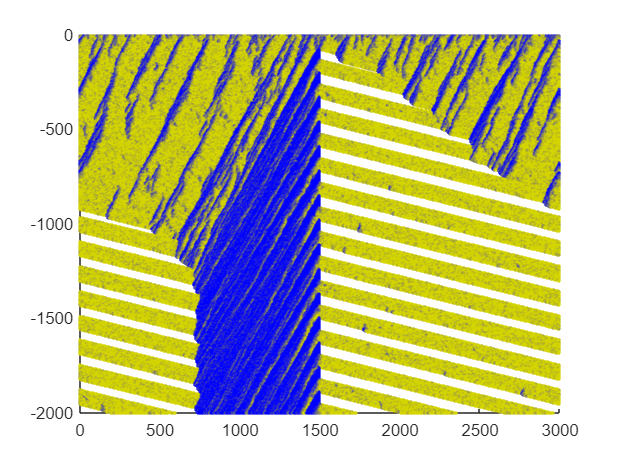

t_rot_Ampel1 = t_gruen_Ampel2;
t_rot_Ampel2 = t_gruen_Ampel1;

[ind1,val1] = Ampel_Nagel_Schreck(dichte1, laenge1, iter, v_max1, p_troedel1, ampel1, t_gruen_Ampel1, t_gruen_Ampel2);
[ind2,val2] = Starte_rote_Ampel_Nagel_Schreck(dichte2, laenge2, iter, v_max2, p_troedel2, ampel2, t_gruen_Ampel2, t_gruen_Ampel1);

% Ringstraße 1
% Zeiten werden für y-Achse gebraucht
tim1 = ones(size(ind1,1),1) * (1:iter);
tim2 = ones(size(ind2,1),1) * (1:iter);

gry_scale = (0:v_max1)' * ones(1,3) / (v_max1+1);
red_scale = gry_scale; red_scale(:,1)=ones((v_max1+1),1);
blu_scale = gry_scale; blu_scale(:,3)=ones((v_max1+1),1);
grn_prp_scale = gry_scale; grn_prp_scale(:,[1 3])=(v_max1:-1:0)'/v_max1 * ones(1,2);
trq_red_scale = gry_scale; trq_red_scale(:,1)=(v_max1:-1:0)'/v_max1;
ylw_blu_scale = gry_scale; ylw_blu_scale(:,3)=(v_max1:-1:0)'/v_max1;

% und plotten
figure(1);
colormap(ylw_blu_scale)
scatter(ind1(:),-tim1(:),[],val1(:)+1,'.');

% Ringstraße 2
% Zeiten werden für y-Achse gebraucht
gry_scale = (0:v_max2)' * ones(1,3) / (v_max2+1);
red_scale = gry_scale; red_scale(:,1)=ones((v_max2+1),1);
blu_scale = gry_scale; blu_scale(:,3)=ones((v_max2+1),1);
grn_prp_scale = gry_scale; grn_prp_scale(:,[1 3])=(v_max2:-1:0)'/v_max2 * ones(1,2);
trq_red_scale = gry_scale; trq_red_scale(:,1)=(v_max2:-1:0)'/v_max2;
ylw_blu_scale = gry_scale; ylw_blu_scale(:,3)=(v_max2:-1:0)'/v_max2;

% und plotten
figure(2);
colormap(ylw_blu_scale)

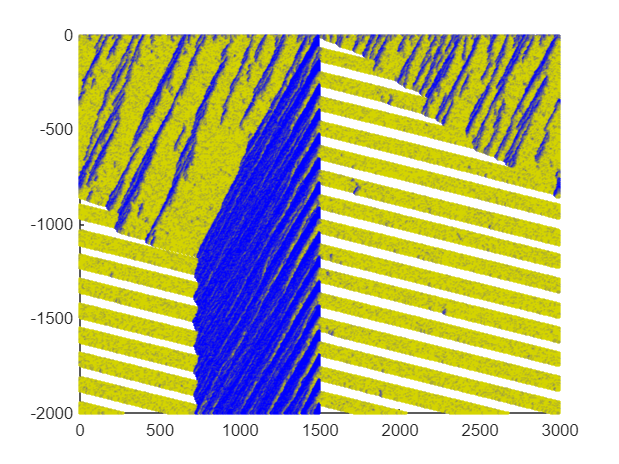

scatter(ind2(:),-tim2(:),[],val2(:)+1,'.');